# ECEN 611 Homework 4: Gap Function and Mutual Inductance for Salient Pole Rotor 

## Problem 2

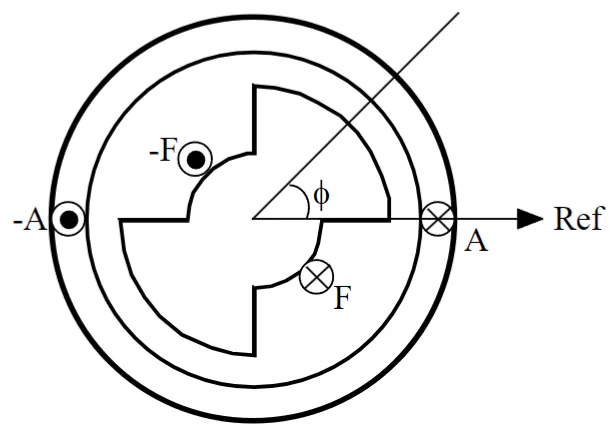

(pole arc = 90 degree)

clearvars 
clc 

### Inverse Gap Function 

*if you could make Problem 1 a function...* 

syms g_min g_max     positive real
syms alpha           positive real 
syms phi                      real 
syms g_phi(phi)
syms theta_r theta 

assume( (alpha > 0) & (alpha <= deg2rad(180)) )

T = 2*pi;
POLEARC = deg2rad(90);
THETA_R = deg2rad(45);

poleArc = alpha;
midArc = T/2 - poleArc;

rotor_profile_theta = [poleArc/2 midArc poleArc midArc poleArc/2];
rotor_profile_turning_phi = [theta_r, theta_r + cumsum(rotor_profile_theta)];

rotor_profile_turning_phi = subs( ...
    rotor_profile_turning_phi, ...
    poleArc, POLEARC ...
)

$$rotor\_profile\_turning\_phi = \left(\begin{array}{cccccc} \theta_{r} & \theta_{r}+\frac{\pi }{4} & \theta_{r}+\frac{3\,\pi }{4} & \theta_{r}+\frac{5\,\pi }{4} & \theta_{r}+\frac{7\,\pi }{4} & \theta_{r}+2\,\pi \end{array}\right)$$

% phi_ref = 0;
% rotor_profile_turning_phi = [phi_ref, rotor_profile_turning_phi]

gap_profile = [g_min, g_max, g_min, g_max, g_min];

firstPhi = rotor_profile_turning_phi(1);
secondPhi = rotor_profile_turning_phi(2);

firstGap = gap_profile(1);

g_phi(phi) = piecewise(firstPhi <= phi < secondPhi, firstGap)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\theta_{r}\leq \varphi \wedge 4\,\varphi <4\,\theta_{r}+\pi \end{array}\right.$$


for k = 2 : length(rotor_profile_turning_phi) - 1 

    thisPhi = rotor_profile_turning_phi(k);
    nextPhi = rotor_profile_turning_phi(k+1); 
    thisGap = gap_profile(k);

    g_phi(phi) = piecewise( ...
        thisPhi <= phi < nextPhi, thisGap, ...
        phi <= thisPhi, g_phi(phi) ...
    ); 
end  

g_phi(phi) = simplify(g_phi)

$$g\_phi(phi) = \left\{ \begin{array}{cl} g_{\min} & \text{ if }\varphi <\theta_{r}+2\,\pi \wedge \theta_{r}+\frac{7\,\pi }{4}\leq \varphi \\ g_{\max} & \text{ if }\varphi <\theta_{r}+\frac{7\,\pi }{4}\wedge \theta_{r}+\frac{5\,\pi }{4}\leq \varphi \\ g_{\min} & \text{ if }\varphi <\theta_{r}+\frac{5\,\pi }{4}\wedge \theta_{r}+\frac{3\,\pi }{4}\leq \varphi \\ g_{\max} & \text{ if }\varphi <\theta_{r}+\frac{3\,\pi }{4}\wedge \theta_{r}+\frac{\pi }{4}\leq \varphi \\ g_{\min} & \text{ if }\theta_{r}\leq \varphi \wedge 4\,\varphi <4\,\theta_{r}+\pi \end{array}\right.$$

g_phi_inv = 1 / g_phi

$$g\_phi\_inv(phi) = \left\{ \begin{array}{cl} \frac{1}{g_{\min}} & \text{ if }\varphi <\theta_{r}+2\,\pi \wedge \theta_{r}+\frac{7\,\pi }{4}\leq \varphi \\ \frac{1}{g_{\max}} & \text{ if }\varphi <\theta_{r}+\frac{7\,\pi }{4}\wedge \theta_{r}+\frac{5\,\pi }{4}\leq \varphi \\ \frac{1}{g_{\min}} & \text{ if }\varphi <\theta_{r}+\frac{5\,\pi }{4}\wedge \theta_{r}+\frac{3\,\pi }{4}\leq \varphi \\ \frac{1}{g_{\max}} & \text{ if }\varphi <\theta_{r}+\frac{3\,\pi }{4}\wedge \theta_{r}+\frac{\pi }{4}\leq \varphi \\ \frac{1}{g_{\min}} & \text{ if }\theta_{r}\leq \varphi \wedge 4\,\varphi <4\,\theta_{r}+\pi \end{array}\right.$$


g_phi_inv_ext(phi) = piecewise( ...
    theta_r - 2*T <= phi < theta_r - T,  g_phi_inv(phi+2*T), ...
    theta_r - T <= phi < theta_r,        g_phi_inv(phi+T), ...
    theta_r <= phi < theta_r + T,        g_phi_inv(phi), ...
    theta_r + T <= phi <= theta_r + 2*T, g_phi_inv(phi-T) ...
)

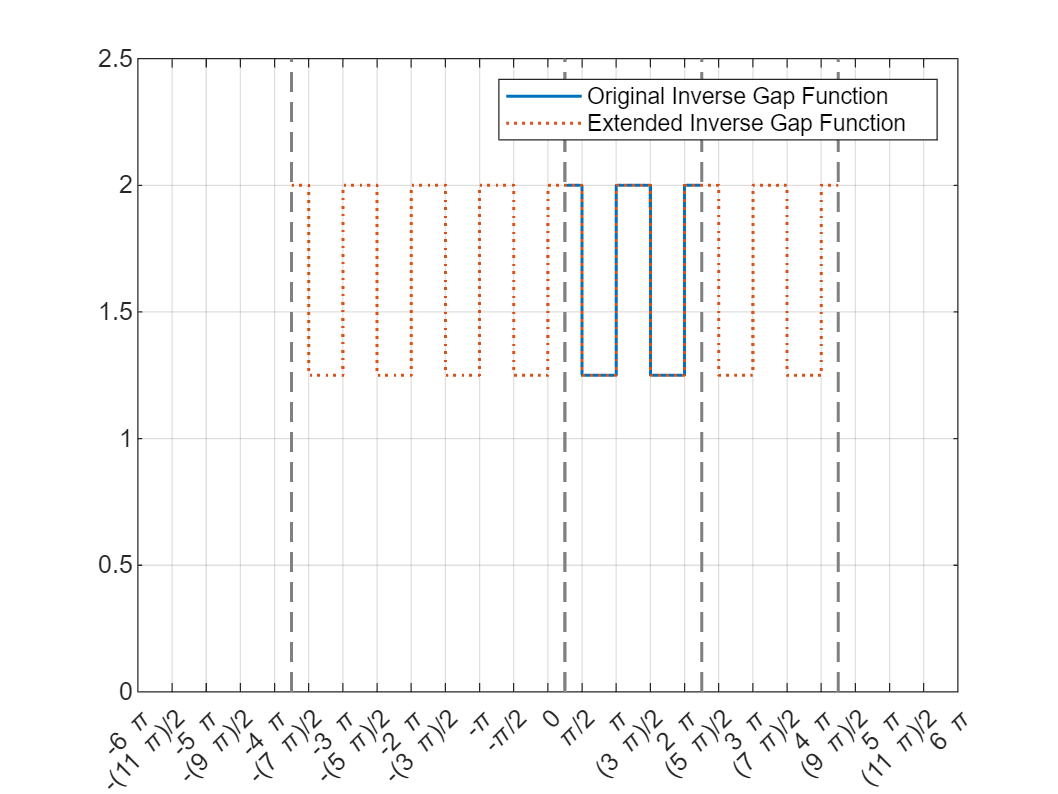

% it was [0 T], now it becomes [theta_r theta_r+T]

vars = [poleArc g_min g_max theta_r];
VALS = [POLEARC 0.5   0.8   THETA_R];

figure 
fplot(subs(g_phi_inv, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Original Inverse Gap Function", ...
      "LineWidth", 1.2)
hold on
fplot(subs(g_phi_inv_ext, vars, VALS), [-3*T 3*T], ...
      "DisplayName", "Extended Inverse Gap Function", ...
      "LineStyle",":", ...
      "LineWidth", 1.2 ...
      )
hold off 
ylim([0 2.5])
grid on 
legend 
ax = gca;
S = sym(ax.XLim(1):pi/2:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### Stator Counting & Winding Function

numberOfConductors = 2; 

syms I positive real 
syms N_s 

NS = 1;

% close the "loop": one turn is at phi=0 and the other T/2
% however, closing the "loop" by winding up to T (same as phi=0) makes
% programming easier because that corresponds to a full period 
turnsStatorNum = [1 -1 1] * N_s;   % number of turns at each location: replace Nt with 1 for simplicity  
turnsStatorPhi = [0 T/2 T];  % angle of each location 

% Initialize the piecewise function with the first interval
phiReference = sym(0); % unique and universal "yardstick" for all angles associated with rotor and stator 

turnsStatorNumLevel = cumsum(turnsStatorNum)

$$turnsStatorNumLevel = \left(\begin{array}{ccc} N_{s} & 0 & N_{s} \end{array}\right)$$

% Initialize the piecewise function with the first interval
statorCountingFunction(phi) = turnsStatorNumLevel(1);

for k = 1:length(turnsStatorPhi)-1
    thisAngle = turnsStatorPhi(k);
    nextPhi = turnsStatorPhi(k+1);
    statorCountingFunction(phi) = piecewise(thisAngle <= phi < nextPhi, turnsStatorNumLevel(k), ...
                                            phiReference <= phi < thisAngle, statorCountingFunction);
end 

#### Original Stator Counting Function φ ∈ [0 T]

disp("Original Stator Counting Function φ ∈ [0 T] :")

Original Stator Counting Function φ ∈ [0 T] :


disp(statorCountingFunction(phi))

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[\pi ,2\,\pi \right)\\ N_{s} & \text{ if }\varphi \in \left[0,\pi \right) \end{array}\right.$$

#### Extended Stator Counting Function φ ∈ [-2T 2T]

statorCountingFunction_ext(phi) = piecewise( ...
    -2*T <= phi < -T, statorCountingFunction(phi+2*T), ...
    -T <= phi < 0, statorCountingFunction(phi+T), ...
    0 <= phi < T, statorCountingFunction(phi), ...
    T <= phi < 2*T, statorCountingFunction(phi-T) ...
);
 
disp("Extended Stator Counting Function φ ∈ [-2T 2T] :")

Extended Stator Counting Function φ ∈ [-2T 2T] :


disp(statorCountingFunction_ext(phi))

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi \in \left[-3\,\pi ,-2\,\pi \right)\\ N_{s} & \text{ if }\varphi \in \left[-4\,\pi ,-3\,\pi \right)\\ 0 & \text{ if }\varphi \in \left[-\pi ,0\right)\\ N_{s} & \text{ if }\varphi \in \left[-2\,\pi ,-\pi \right)\\ 0 & \text{ if }\varphi \in \left[\pi ,2\,\pi \right)\\ N_{s} & \text{ if }\varphi \in \left[0,\pi \right)\\ 0 & \text{ if }\varphi \in \left[3\,\pi ,4\,\pi \right)\\ N_{s} & \text{ if }\varphi \in \left[2\,\pi ,3\,\pi \right) \end{array}\right.$$

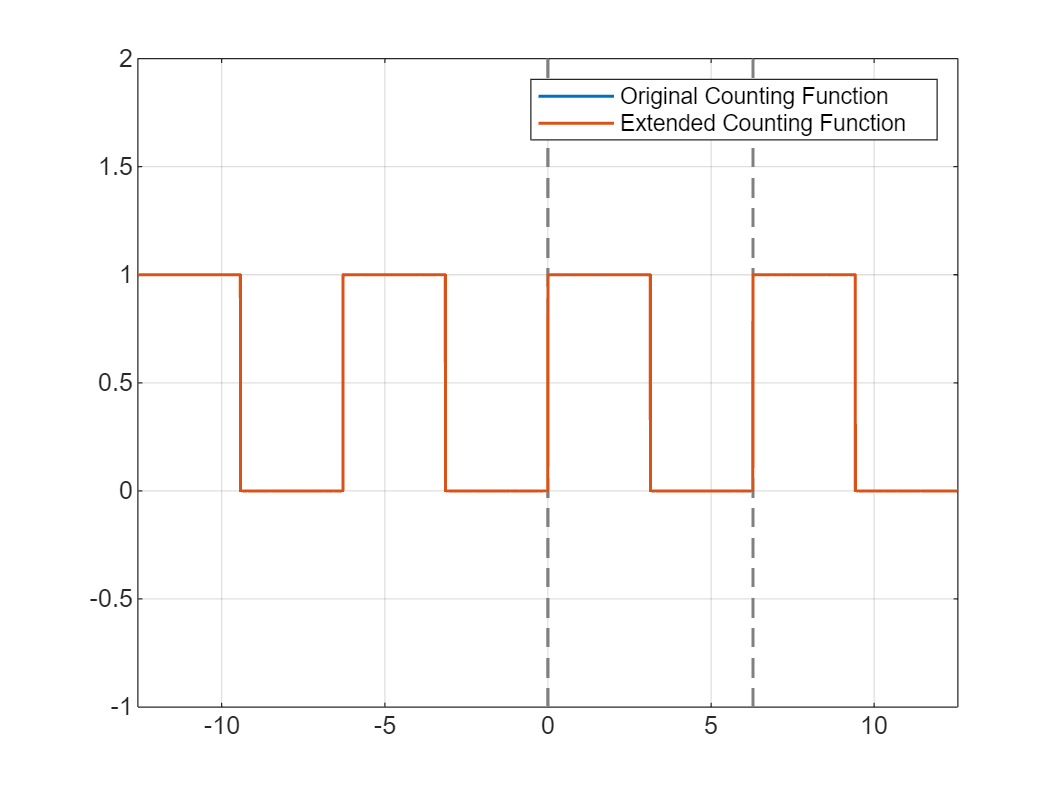


figure 
fplot(subs(statorCountingFunction(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Original Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(statorCountingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Counting Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-1 2])
grid on  
legend 

#### Extended Stator Winding Function φ ∈ [-2T 2T]

statorCountingFunction_ext_avg = 1/T * int(statorCountingFunction_ext, phi, [0 T]);
statorWindingFunction_ext = statorCountingFunction_ext - statorCountingFunction_ext_avg

$$statorWindingFunction\_ext(phi) = \left\{ \begin{array}{cl} -\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-3\,\pi ,-2\,\pi \right)\\ N_{s}-\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-4\,\pi ,-3\,\pi \right)\\ -\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-\pi ,0\right)\\ N_{s}-\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[-2\,\pi ,-\pi \right)\\ -\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[\pi ,2\,\pi \right)\\ N_{s}-\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[0,\pi \right)\\ -\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[3\,\pi ,4\,\pi \right)\\ N_{s}-\frac{5734161139222659\,\pi \,N_{s}}{36028797018963968} & \text{ if }\varphi \in \left[2\,\pi ,3\,\pi \right) \end{array}\right.$$

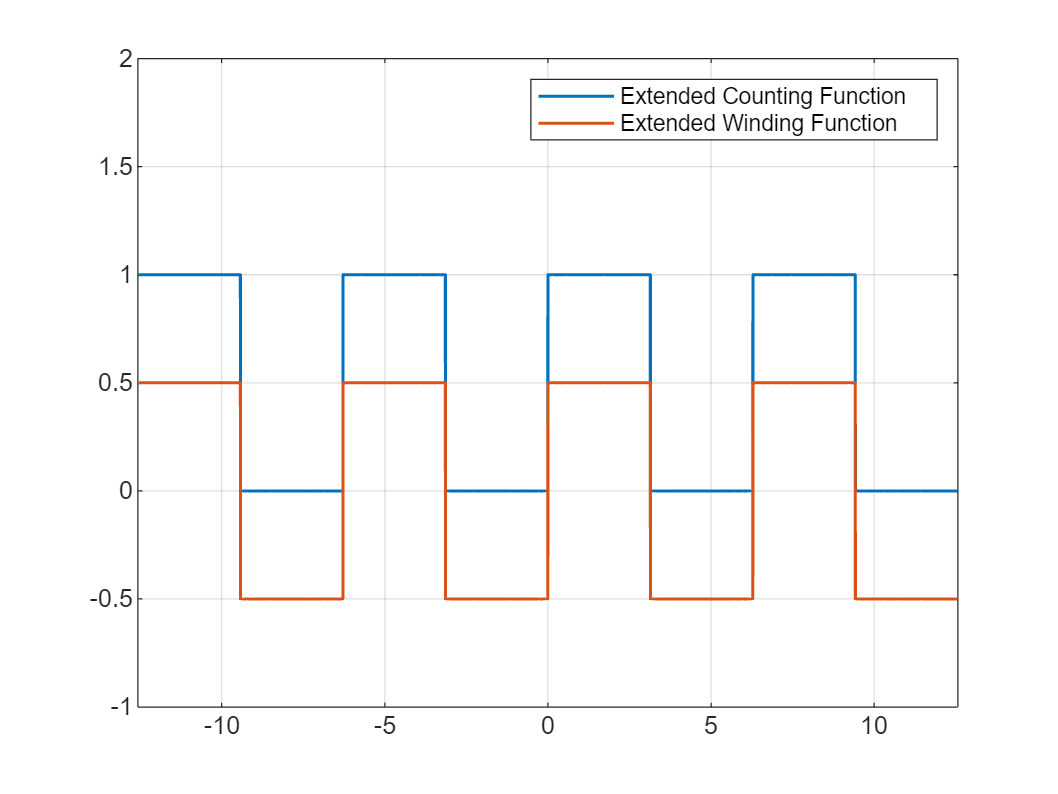


figure 
fplot(subs(statorCountingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(statorWindingFunction_ext(phi), N_s, NS), [-2*T 2*T], ...
    "DisplayName", "Extended Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-1 2])
grid on  
legend 

### Rotor Counting & Winding Function 

% rotor_profile_theta = [poleArc/2 midArc poleArc midArc poleArc/2];
% rotor_profile_turning_phi = [theta_r, theta_r + cumsum(rotor_profile_theta)];
% 
% rotor_profile_turning_phi = subs( ...
%     rotor_profile_turning_phi, ...
%     poleArc, POLEARC ...
% )
syms N_r 
NR = 1;

turnsRotorNum = [0    -1     1    0 ] * N_r;   % number of turns at each location: replace Nt with 1 for simplicity  
turnsRotorPhi = [0   T/4   T/2  T/4 ];  % angle of each location

turnsRotorNumLevel = cumsum(turnsRotorNum)

$$turnsRotorNumLevel = \left(\begin{array}{cccc} 0 & -N_{r} & 0 & 0 \end{array}\right)$$


rotor_winding_turning_phi = theta_r + cumsum(turnsRotorPhi)

$$rotor\_winding\_turning\_phi = \left(\begin{array}{cccc} \theta_{r} & \theta_{r}+\frac{\pi }{2} & \theta_{r}+\frac{3\,\pi }{2} & \theta_{r}+2\,\pi \end{array}\right)$$

% Initialize the piecewise function with the first interval
rotorCountingFunction(phi) = turnsRotorNumLevel(1);

for k = 1:length(rotor_winding_turning_phi)-1
    
    thisPhi = rotor_winding_turning_phi(k);
    nextPhi = rotor_winding_turning_phi(k+1);

    rotorCountingFunction(phi) = piecewise(thisPhi <= phi < nextPhi, turnsRotorNumLevel(k), ...
                                           phiReference <= phi < thisPhi, rotorCountingFunction);
end 

#### Original Rotor Counting Function φ ∈ [θr θr+T]

disp("Original Rotor Counting Function: ");

Original Rotor Counting Function: 


disp(rotorCountingFunction(phi));

$$\left\{ \begin{array}{cl} 0 & \text{ if }\varphi <\theta_{r}+2\,\pi \wedge \theta_{r}+\frac{3\,\pi }{2}\leq \varphi \\ -N_{r} & \text{ if }\varphi <\theta_{r}+\frac{3\,\pi }{2}\wedge \theta_{r}+\frac{\pi }{2}\leq \varphi \wedge 0\leq \varphi \\ 0 & \text{ if }\varphi <\theta_{r}+\frac{\pi }{2}\wedge 0\leq \varphi \wedge \left(\varphi <\theta_{r}\vee \left(\theta_{r}\leq \varphi \wedge 2\,\varphi <2\,\theta_{r}+\pi \right)\right) \end{array}\right.$$

#### Extended Rotor Counting Function φ ∈ [θr-2T θr+2T]

rotorCountingFunction_ext(phi) = piecewise( ...
    theta_r - 2*T <= phi < theta_r - T, rotorCountingFunction(phi+2*T), ...
    theta_r - T <= phi < theta_r,       rotorCountingFunction(phi+T), ...
    theta_r <= phi < theta_r + T,       rotorCountingFunction(phi), ...
    theta_r + T <= phi < theta_r + 2*T, rotorCountingFunction(phi-T) ...
)


% figure 
% fplot(subs(rotorCountingFunction(phi), [theta_r N_r], [0 NR]), [-2*T 2*T], ...
%     "DisplayName", "Original Counting Function", ...
%     "LineWidth", 1.2)
% hold on 
% fplot(subs(rotorCountingFunction_ext(phi), [theta_r N_r], [0 NR]), [-2*T 2*T], ...
%     "DisplayName", "Extended Counting Function", ...
%     "LineWidth", 1.2)
% hold off 
% ylim([-2 2])
% grid on 
% 
% ax = gca;
% S = sym(ax.XLim(1):pi/2:ax.XLim(2));
% ax.XTick = double(S);
% ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

#### Extended Rotor Winding Function φ ∈ [θr-2T θr+2T]

% assume( theta < T )

rotorCountingFunction_ext_avg = 1/T * int( subs(rotorCountingFunction_ext, theta_r, THETA_R), phi, [0 T]);
rotorWindingFunction_ext = rotorCountingFunction_ext - rotorCountingFunction_ext_avg

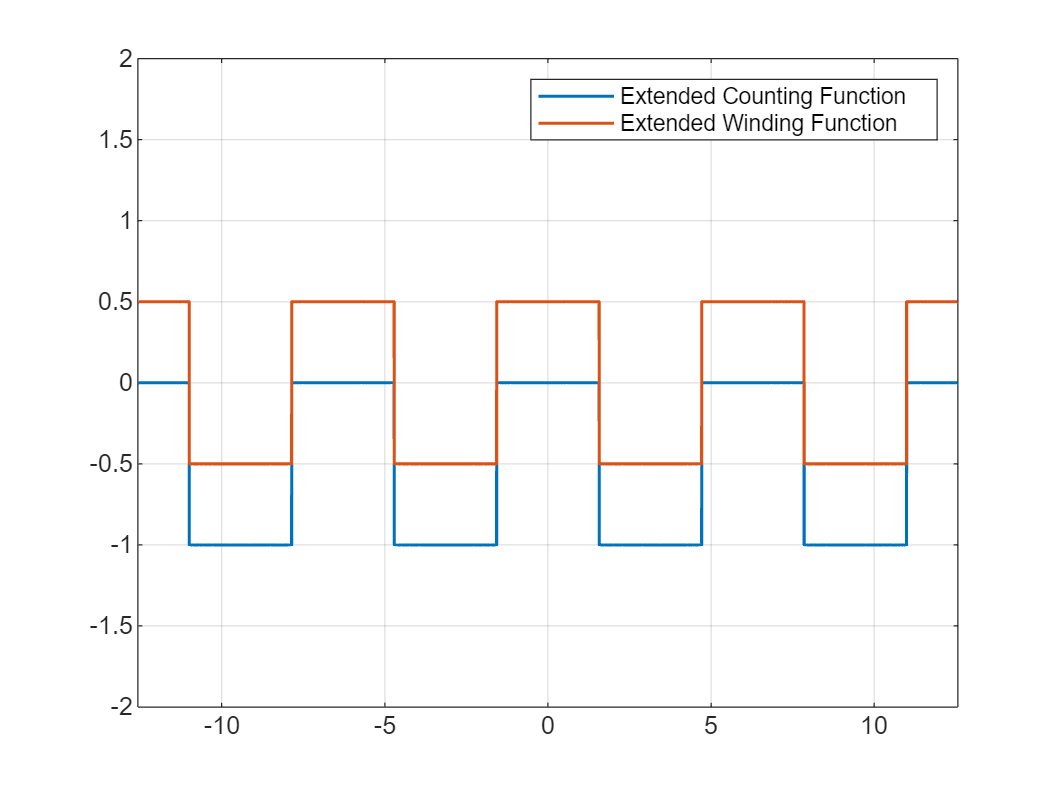


figure 
fplot(subs(rotorCountingFunction_ext(phi),[theta_r N_r], [0 NR]), [-2*T 2*T], ...
    "DisplayName", "Extended Counting Function", ...
    "LineWidth", 1.2)
hold on 
fplot(subs(rotorWindingFunction_ext(phi),[theta_r N_r], [0 NR]), [-2*T 2*T], ...
    "DisplayName", "Extended Winding Function", ...
    "LineWidth", 1.2)
hold off 
ylim([-2 2])
grid on  
legend 

### (a) Magnetizing inductance of winding A on the stator

digits(4)

syms mu_o r l 
Lss = mu_o*r*l * int( statorCountingFunction * statorWindingFunction_ext * subs(g_phi_inv_ext, theta_r, [0 THETA_R T/2]), ...
                      phi, [0 T]);

Lss = simplify( vpa(Lss') )

$$Lss = \left(\begin{array}{c} \frac{0.7854\,{\left(\bar{N_{s}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.7854\,{\left(\bar{N_{s}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.7854\,{\left(\bar{N_{s}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}} \end{array}\right)$$

### (b) Magnetizing inductance of winding F on the rotor

THETA_R_ARRAY = 0: T/8 : T;

rotorIntegrand = subs( ...
    rotorCountingFunction * rotorWindingFunction_ext * g_phi_inv_ext, ...
    theta_r, THETA_R_ARRAY);
Lrr = mu_o*r*l * int( rotorIntegrand, phi, [0 T]);

Lrr = simplify( vpa(Lrr') )

$$Lrr = \left(\begin{array}{c} \frac{0.7854\,{\left(\bar{N_{r}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.7854\,{\left(\bar{N_{r}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.7854\,{\left(\bar{N_{r}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.3927\,{\left(\bar{N_{r}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+2.0\,g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.3927\,{\left(\bar{N_{r}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{0.3927\,{\left(\bar{N_{r}}\right)}^{2}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}}{g_{\max}}\\ 0\\ 0\\ 0 \end{array}\right)$$


syms K
Lrr_simplified = double( subs(Lrr, [(N_r^2*l*mu_o*r)' vars], [1 VALS]) )

Lrr_simplified =     2.5526
    2.5526
    2.5526
    2.0617
    1.2763
    0.4909
         0
         0
         0


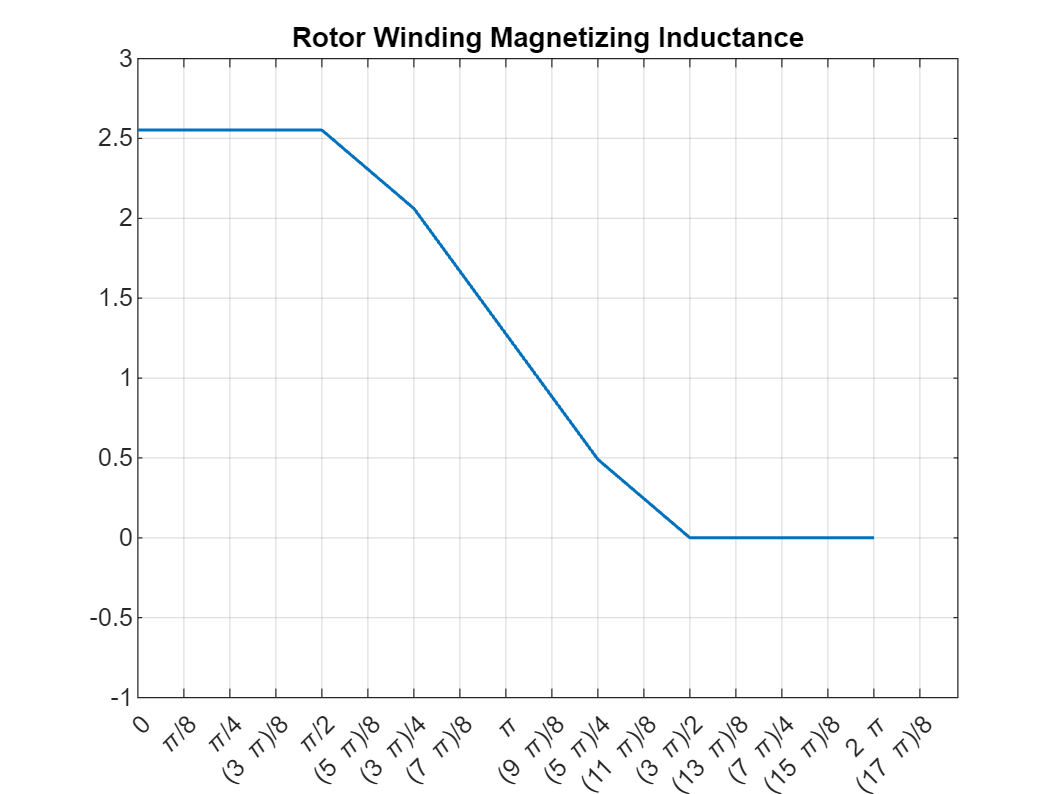

figure 
plot(THETA_R_ARRAY, Lrr_simplified, ...
    "LineWidth", 1.2)
ylim([-1 3])
grid on  

title("Rotor Winding Magnetizing Inductance")
ax = gca;
S = sym(ax.XLim(1):pi/8:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);

### (c) Mutual inductance between stator and rotor for the following salient pole synchronous machine

THETA_R_ARRAY = 0: T/8 : T;

Lsr_integrand = subs( ...
    statorCountingFunction * rotorWindingFunction_ext * g_phi_inv_ext, ...
    theta_r, THETA_R_ARRAY);
Lsr = mu_o*r*l * int( Lsr_integrand, phi, [0 T]);

Lsr = simplify( vpa(Lsr') )

$$Lsr = \left(\begin{array}{c} \frac{90949\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{100000000000000000\,g_{\min}\,g_{\max}}\\ \frac{1.0e-17\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(90950.0\,g_{\min}+7.854e+16\,g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{3927\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{5000\,g_{\min}\,g_{\max}}\\ \frac{1.0e-17\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(90950.0\,g_{\min}+7.854e+16\,g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{90949\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{100000000000000000\,g_{\min}\,g_{\max}}\\ \frac{1.0e-17\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(90950.0\,g_{\min}-7.854e+16\,g_{\max}\right)}{g_{\min}\,g_{\max}}\\ -\frac{3927\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{5000\,g_{\min}\,g_{\max}}\\ \frac{1.0e-17\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(90950.0\,g_{\min}-7.854e+16\,g_{\max}\right)}{g_{\min}\,g_{\max}}\\ \frac{90949\,\bar{N_{r}}\,\bar{N_{s}}\,\bar{l}\,\bar{\mu_{o}}\,\bar{r}\,\left(g_{\min}+g_{\max}\right)}{100000000000000000\,g_{\min}\,g_{\max}} \end{array}\right)$$


Lsr_simplified = double( subs(Lsr, [(N_r*N_s*l*mu_o*r)' vars], [1 VALS]) )

Lsr_simplified =     0.0000
    1.5708
    2.5526
    1.5708
    0.0000
   -1.5708
   -2.5526
   -1.5708
    0.0000


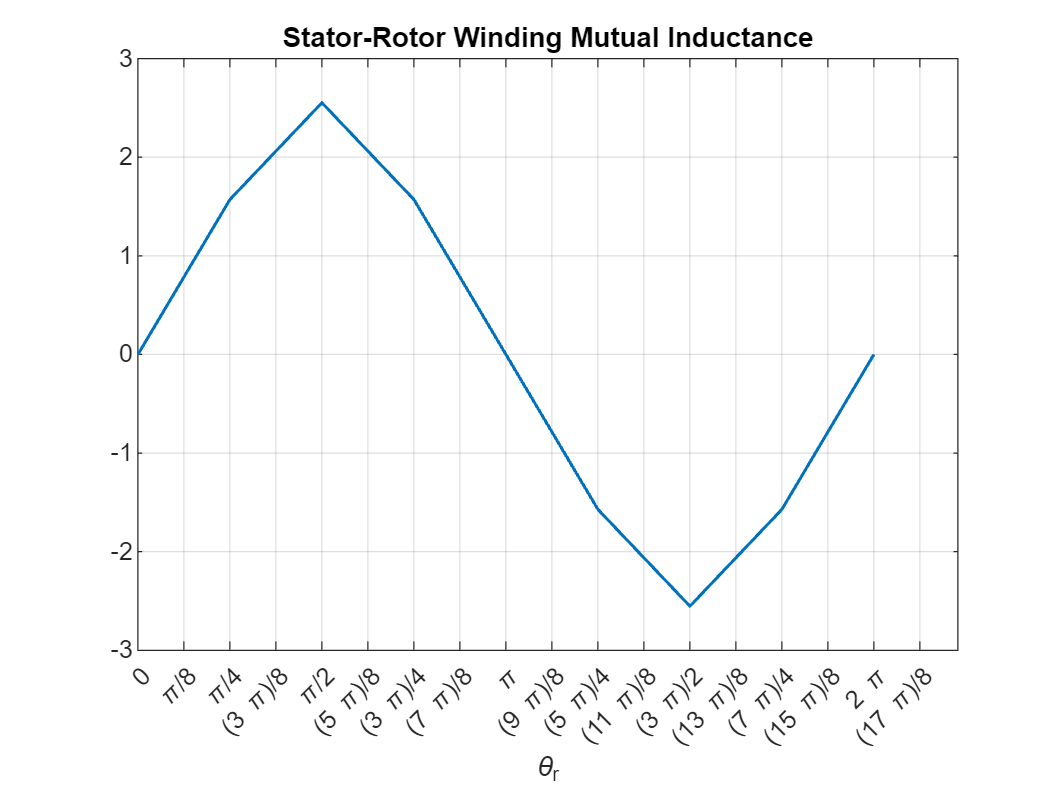


figure 
plot(THETA_R_ARRAY, Lsr_simplified, ...
    "LineWidth", 1.2)
ylim([-3 3])
title("Stator-Rotor Winding Mutual Inductance")
xlabel("\theta_r")
grid on  

ax = gca;
S = sym(ax.XLim(1):pi/8:ax.XLim(2));
ax.XTick = double(S);
ax.XTickLabel = arrayfun(@texlabel,S,'UniformOutput',false);